# RUN

## Description

- ***This script runs the Half Car Model which uses Acceleration as Input***

- ***The Acceleration is CONVERTED to a Driving/Braking Torque which is then used as an input***

- It is triggered when the project is first started.

- It must be run everytime the user makes a change to any input of the half car

## Functions of Script

- Initializes the `Hcar.m `class. 

- Computes the initial conditions of the linearized model about static equilibrium using `fsolve`

- Runs the simulation using (by default) `ode15s`. 

## Modifications

- The solver can be modeified by simple replacing `ode15s `with any other [solver which Matlab supports](https://nl.mathworks.com/help/matlab/math/choose-an-ode-solver.html)

- Matlab solvers allow for setting custom solver options. This can be modified by modifying the `options `variable in this document. For information of solver options that Matlab has click [here](https://nl.mathworks.com/help/matlab/math/summary-of-ode-options.html). For information on setting these options, click 

###    * Initial condition Guess*

- *The initial condition guess may need to be updated if the half car properties or half car component properties are modified. *

- *Based on the change of the half, make an educated guess of what the initial condition could be using simple calculations and assign this to the *`initGuess `*variable.*

## More Information

- [Solving Stiff ODEs](https://nl.mathworks.com/help/matlab/math/solve-stiff-odes.html)

- [Solving Non-Stiff ODEs](https://nl.mathworks.com/help/matlab/math/solve-nonstiff-odes.html)

## *----------------------------------- SCRIPT -----------------------------------------*

### Initial Conditions

This section computes the initial conditions which the Half Car attains when in static or steady state equilbrium

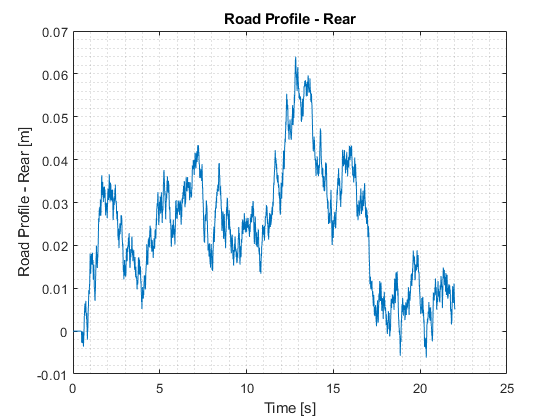

%%%%%%%%%%%%%%%%%%%%%%% Safety %%%%%%%%%%%%%%%%%%%%%%%%%%%%
A = exist('hcar','var');

if A == 0
    hcar = HCar;
end
clear A;
SimulationInput;

 -------- FRONT SPRINGS -------- 


forceDefData = 6×2 table
    Deflection_m    Force_N
    ____________    _______

           0             0 
        0.02          6780 
        0.04         13560 
        0.06         20340 
        0.08         27120 
         0.1         33900 


 -------- REAR SPRINGS -------- 


forceDefData = 6×2 table
    Deflection_m    Force_N
    ____________    _______

           0             0 
        0.02          6780 
        0.04         13560 
        0.06         20340 
        0.08         27120 
         0.1         33900 


 -------- FRONT BUMPSTOPS -------- 


forceDefData = 29×2 table
    Deflection_m    Force_N
    ____________    _______

            0            0 
       0.0005         95.8 
        0.001        207.6 
       0.0015          324 
        0.002        437.7 
       0.0025        545.2 
        0.003        647.3 
       0.0035        748.4 
        0.004        857.2 
       0.0045        986.3 
        0.005       1152.4 
       0.0055       1375.9 
        0.006       1681.5 
       0.0065       2097.9 
        0.007       2657.4 
       0.0075       3396.9 


 -------- REAR BUMPSTOPS -------- 


forceDefData = 29×2 table
    Deflection_m    Force_N
    ____________    _______

            0            0 
       0.0005         95.8 
        0.001        207.6 
       0.0015          324 
        0.002        437.7 
       0.0025        545.2 
        0.003        647.3 
       0.0035        748.4 
        0.004        857.2 
       0.0045        986.3 
        0.005       1152.4 
       0.0055       1375.9 
        0.006       1681.5 
       0.0065       2097.9 
        0.007       2657.4 
       0.0075       3396.9 


 -------- FRONT COILOVER -------- 
 -------- REAR COILOVER -------- 
 -------- FRONT DAMPER  -------- 


forceVelData = 11×2 table
    Shaft_Velocity_mps    Force_N
    __________________    _______

         -0.39061           -2409
         -0.07942         -879.13
          -0.0258         -287.18
         -0.01291         -123.84
         -0.00745         -77.754
                0               0
          0.00752          76.518
          0.01288          125.72
           0.0258          321.85
          0.07943          880.96
             0.39          1703.4


 -------- REAR DAMPER -------- 


forceVelData = 11×2 table
    Shaft_Velocity_mps    Force_N
    __________________    _______

         -0.39061           -2409
         -0.07942         -879.13
          -0.0258         -287.18
         -0.01291         -123.84
         -0.00745         -77.754
                0               0
          0.00752          76.518
          0.01288          125.72
           0.0258          321.85
          0.07943          880.96
             0.39          1703.4


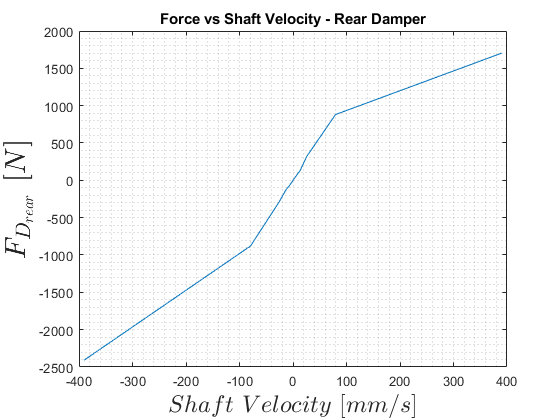

 -------- FRONT TIRE-------- 
To edit coefficients navigate to TireCus.m class


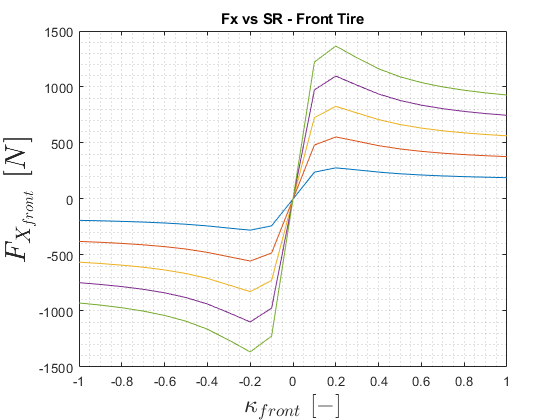

 -------- REAR TIRE-------- 
To edit coefficients navigate to TireCus.m class


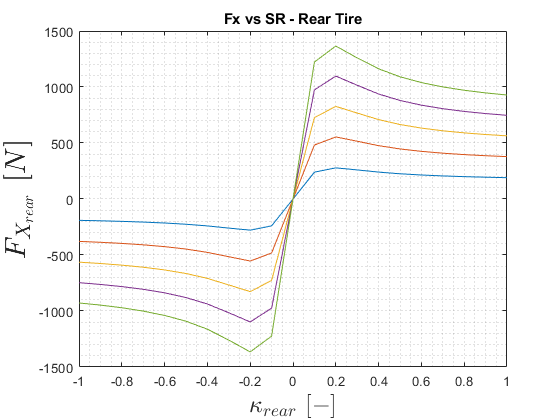

 -------- FRONT SUSPENSION -------- 
 -------- REAR SUSPENSION -------- 


aeroMapImport = 2501×5 table
    Front_Ride_Height_mm    Rear_Ride_Height_mm    DownforceCoefficient    DragCoefficient    Aerobalance_Percent
    ____________________    ___________________    ____________________    _______________    ___________________

             30                     30                    5.843                 0.995               45.102       
             30                     31                    5.869                 0.996                45.11       
             30                     32                    5.893                 0.997                45.12       
             30                     33                    5.914                 0.997               45.131       
             30                     34                    5.932                 0.998               45.143       
  

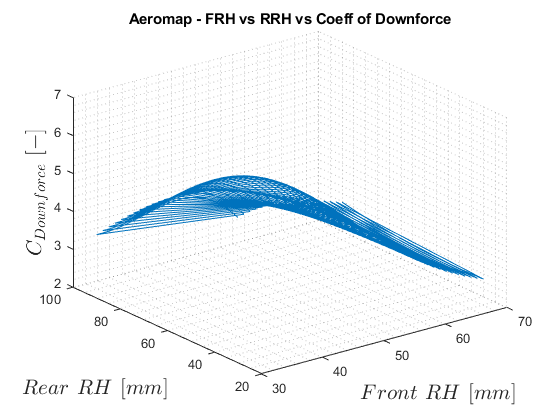

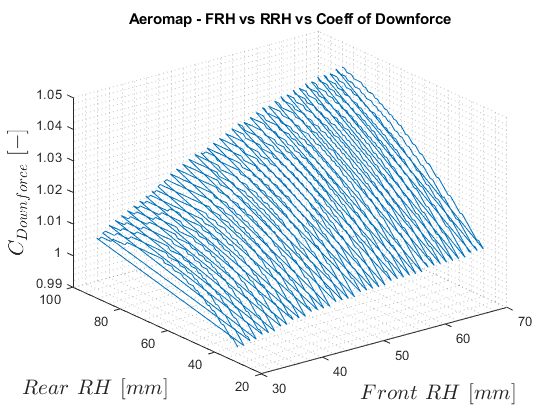

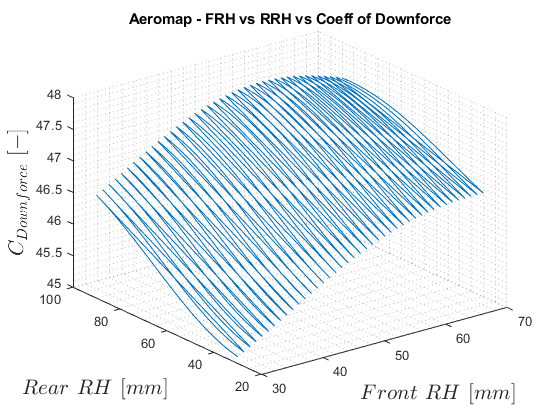

ComponentInput;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


STUCT Variable of this class is : `r`

% Computing the Initial Conditions of the Half Car

% Initial Conditions Vehicle
r.Vx = hcar.simInputs3.vx;
r.initVehicle = [0 r.Vx]

r = struct with fields:
             Vx: 0.2778
    initVehicle: [0 0.2778]
      initGuess: [-0.0600 0 -0.0400 -0.0400]
        initDef: [-0.0337 -1.7720e-08 -0.0119 -0.0119]
        initVel: [0 0 0 0]
            rE1: 0.2131
         omega1: 1.3033
       initNSM1: [0 1.3033 0]
            rE2: 0.2131
         omega2: 1.3033
       initNSM2: [0 1.3033 0]
           init: [-0.0337 -1.7720e-08 -0.0119 -0.0119 0 0 0 0 0 1.3033 0 0 1.3033 0 0 0.2778]
        options: [1×1 struct]



% Intial Deflection Guess
r.initGuess = [-0.06 0.0000 -0.04 -0.04];

% FSOLVE to compute the initial Defletion
r.initDef = fsolve(@(z)HalfCar_InitCond11_Aero(z,hcar),r.initGuess);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



% Initial Velocities
r.initVel = [0 0 0 0];

% Initial conditionso of Unsprung Mass - 1
r.rE1 = hcar.tire1.unloadedRadius - -r.initDef(3);
r.omega1 = r.Vx/(r.rE1);
r.initNSM1  = [0 r.omega1 0];

% Initial conditionso of Unsprung Mass - 1
r.rE2 = hcar.tire2.unloadedRadius - -r.initDef(4);
r.omega2 = r.Vx/(r.rE2);
r.initNSM2 = [0 r.omega2 0];

% Array of Initial Deflections and Velocities
r.init = [r.initDef r.initVel r.initNSM1... 
    r.initNSM2 r.initVehicle]; 

% Display to user
disp("Initial Conditions of Model:-");

Initial Conditions of Model:-


disp(r.init);

  Columns 1 through 15

   -0.0337   -0.0000   -0.0119   -0.0119         0         0         0         0         0    1.3033         0         0    1.3033         0         0

  Column 16

    0.2778



### Solver Options

% Creating Solver Options variables
r.options = odeset('OutputFcn',@odeplot,'MaxStep',0.1,...
    "RelTol",1e-1,"AbsTol",1e-2)

r = struct with fields:
             Vx: 0.2778
    initVehicle: [0 0.2778]
      initGuess: [-0.0600 0 -0.0400 -0.0400]
        initDef: [-0.0337 -1.7720e-08 -0.0119 -0.0119]
        initVel: [0 0 0 0]
            rE1: 0.2131
         omega1: 1.3033
       initNSM1: [0 1.3033 0]
            rE2: 0.2131
         omega2: 1.3033
       initNSM2: [0 1.3033 0]
           init: [-0.0337 -1.7720e-08 -0.0119 -0.0119 0 0 0 0 0 1.3033 0 0 1.3033 0 0 0.2778]
        options: [1×1 struct]


### Numerical Integration

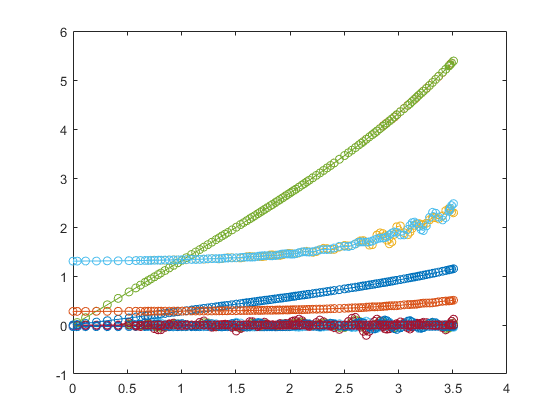

% Solving the Half Car Vehicle Model 
% -> Default solver: ode15s 
% -> Solution at each time-step will be displayed using a figure 
[t,y] = ode23t(@(t,z)HalfCarModel_11_AeroM(t,z,hcar), ...
    [hcar.simInputs3.tStart hcar.simInputs3.tEnd],[r.init],r.options);